### Auxilliary functions for better display :

- scale - takes the numbered samples and returns the time/frequency domain axis : $1\ldotp \ldotp \ldotp N\to 0\ldotp \ldotp \ldotp T$

- map - chooses the relative time stamp inside the new axis : $t_n \to \textrm{idx}\left(t_n \right)$

clc ; clear ;

scale = @(N,T_s) (1:N).*(T_s/N);

map = @(y,x) floor(y * length(x)/x(end));

### Part 1 : Anti-aliasing

We are asked to create a square signal and sample it with the following characteristics:

- sample time - 1 sec

- sample rate - 3200khz

- signal base frequency - 250hz

- signal amplitude - based on equipment accuracy range = 700mv

We reconstruct the signal for 2 cases :

- reconstruct the signal as it is 

- applying anti-aliasing filter before reconstructing

Here are the results :

% Load variables
square_NO_filter_250hz_3200hz_1sec = load("C:\Users\yizharf\coding\bgu\dsp_lab\lab3\part1\square_NO_filter_250hz_3200hz_1sec.mat");
square_without_anti_aliasing = square_NO_filter_250hz_3200hz_1sec.signal;
clear square_NO_filter_250hz_3200hz_1sec;

% Display results
square_without_anti_aliasing

square_without_anti_aliasing =    -0.7437   -0.7275   -0.7115   -0.6884   -0.6744   -0.6595    0.7199    0.7014    0.6900    0.6724    0.6532    0.6184   -0.7564   -0.7441   -0.7128   -0.7014   -0.6865   -0.6709    0.8656    0.7154    0.6971    0.6845    0.6617    0.6474    0.6292   -0.7584   -0.7437   -0.7184   -0.7057   -0.6637   -0.6676    0.7105    0.7092    0.6919    0.6750    0.6627    0.6412    0.6236   -0.7509   -0.7340   -0.7193   -0.7008   -0.6829   -0.6712    0.7245    0.7251    0.6949    0.6727    0.6623    0.6461


#### Signal without anti-aliasing filter (time domain):

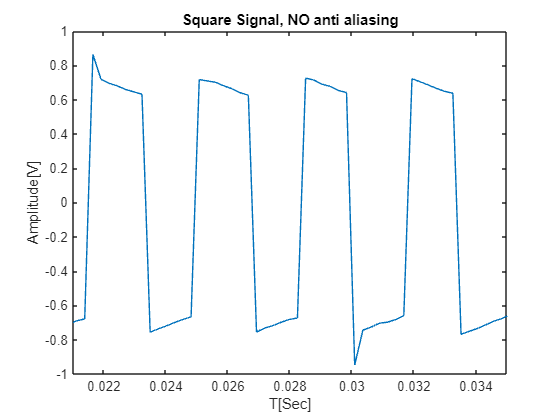

N_without = length(square_without_anti_aliasing);
Ts_without = 1;
T = linspace(0,Ts_without,N_without);


figure;
plot(T,square_without_anti_aliasing);

title("Square Signal, NO anti aliasing")

xlabel("T[Sec]")
ylabel("Amplitude[V]")
xlim([0.021,0.035])

#### Signal without anti-aliasing filter (frequency domain):

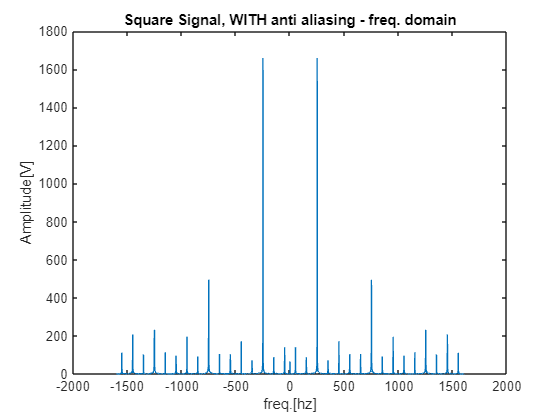

square_without_anti_aliasing_freq = fftshift(fft(square_without_anti_aliasing)) ;
fs_without = 3200 ;

f_without = linspace(-fs_without/2,fs_without/2,N_without);

figure;
plot(f_without,abs(square_without_anti_aliasing_freq));

title("Square Signal, WITH anti aliasing - freq. domain")

xlabel("freq.[hz]")
ylabel("Amplitude[V]")

% Load variables
square_WITH_filter_250hz_3200hz_1sec = load("C:\Users\yizharf\coding\bgu\dsp_lab\lab3\part1\square_WITH_filter_250hz_3200hz_1sec.mat");
square_with_anti_aliasing = square_WITH_filter_250hz_3200hz_1sec.signal;
clear square_WITH_filter_250hz_3200hz_1sec;

% Display results
square_with_anti_aliasing

square_with_anti_aliasing =     0.6900    0.6555    0.6324   -0.1430   -0.9464   -0.6416   -0.7580   -0.6738   -0.6930   -0.3850    0.8263    0.6643    0.6988    0.6578    0.6526    0.5843   -0.4380   -0.8725   -0.6608   -0.7411   -0.6757   -0.6858   -0.1599    0.9102    0.6103    0.7238    0.6399    0.6594    0.5062   -0.6868   -0.7863   -0.6975   -0.7210   -0.6832   -0.6670    0.1410    0.9086    0.6100    0.7251    0.6409    0.6594    0.3433   -0.8602   -0.7014   -0.7271   -0.6933   -0.6855   -0.6061    0.4262    0.8324


#### Signal WITH anti-aliasing filter:

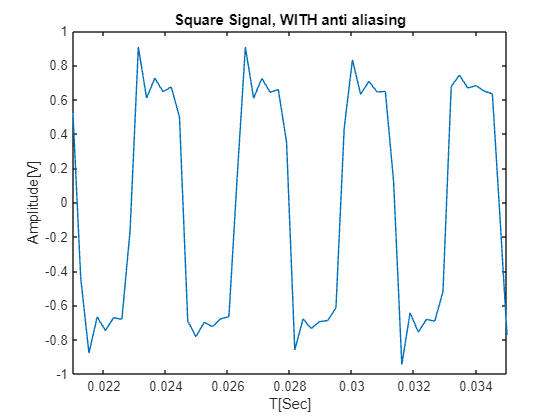

N_with = length(square_with_anti_aliasing);
Ts_with = 1;
T = linspace(0,Ts_with,N_with);


figure;
plot(T,square_with_anti_aliasing);

title("Square Signal, WITH anti aliasing")

xlabel("T[Sec]")
ylabel("Amplitude[V]")
xlim([0.021,0.035])

#### Signal WITH anti-aliasing filter (frequency domain):

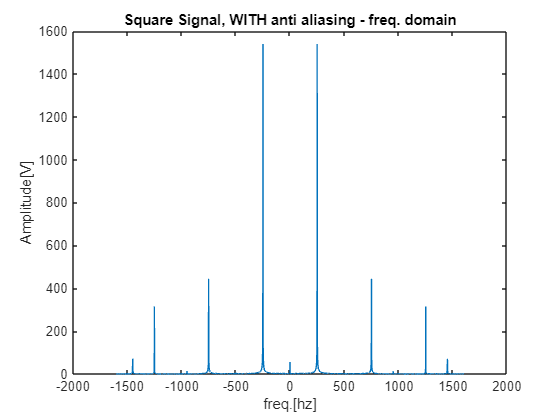

square_with_anti_aliasing_freq = fftshift(fft(square_with_anti_aliasing)) ;
fs_with = 3200 ;

f_with = linspace(-fs_with/2,fs_with/2,N_with);

figure;
plot(f_with,abs(square_with_anti_aliasing_freq));

title("Square Signal, WITH anti aliasing - freq. domain")

xlabel("freq.[hz]")
ylabel("Amplitude[V]")

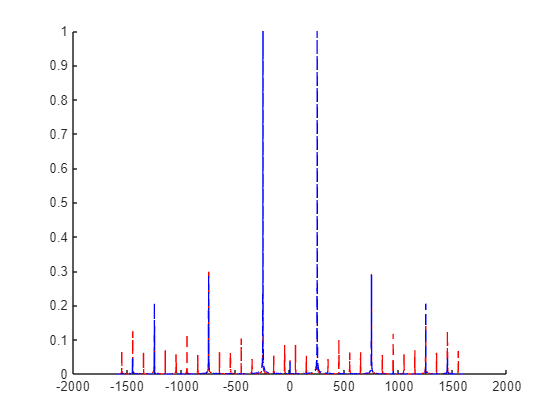

figure ; 
hold on ;

plot(f_without,abs(square_without_anti_aliasing_freq)/max(abs(square_without_anti_aliasing_freq)), "--r");
plot(f_with,abs(square_with_anti_aliasing_freq)/max(abs(square_with_anti_aliasing_freq)), "--b");

hold off ;

#### Zero - Padd original signal

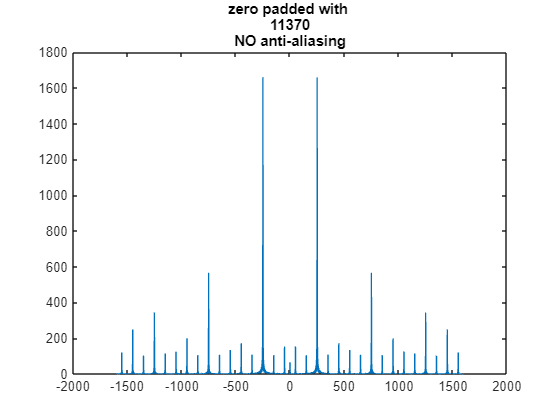

padding = N_without*3;
N_without_padd = N_without + padding;

square_without_anti_aliasing_padded = [square_without_anti_aliasing , zeros(1,padding)];
square_without_anti_aliasing_freq_padded = fftshift(fft(square_without_anti_aliasing_padded));

fs_without_padd = linspace(-1600,1600,N_without_padd);

figure;
plot(fs_without_padd,abs(square_without_anti_aliasing_freq_padded))
title(["zero padded with ", num2str(padding),"NO anti-aliasing"])

#### Zero - Padd anti-aliased signal

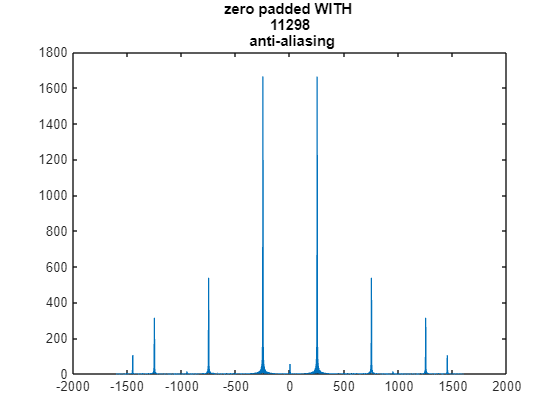

padding = N_with*3;
N_with_padd = N_with + padding;

square_with_anti_aliasing_padded = [square_with_anti_aliasing , zeros(1,padding)];
square_with_anti_aliasing_freq_padded = fftshift(fft(square_with_anti_aliasing_padded));

f_with_padd = linspace(-1600,1600,N_with_padd);

figure;
plot(f_with_padd,abs(square_with_anti_aliasing_freq_padded))
title(["zero padded WITH ", num2str(padding)," anti-aliasing"])

### Part 2 : Quantization

% Load variables
triangular_250hz_7537hz = load("C:\Users\yizharf\coding\bgu\dsp_lab\lab3\part2\triangular_250hz_7537hz.mat");
triangle = triangular_250hz_7537hz.signal;
clear triangular_250hz_7537hz;

% Display results
triangle

triangle =     0.2265    0.3280    0.4470    0.5300    0.6347    0.7323    0.7193    0.6080    0.4955    0.3852    0.2802    0.1761    0.0622   -0.0467   -0.1453   -0.2539   -0.3583   -0.4699   -0.5417   -0.6582   -0.7571   -0.7564   -0.6520   -0.5343   -0.4221   -0.3251   -0.2041   -0.1023    0.0122    0.1136    0.2054    0.3166    0.4243    0.5199    0.6152    0.7183    0.7371    0.6272    0.5169    0.4038    0.2948    0.1719    0.0766   -0.0200   -0.1378   -0.2406   -0.3372   -0.4380   -0.5414   -0.6416


#### Import and display trianglular signal 

- Sampling length : $L_0 \ge \;3000\textrm{hz}$

- base freq. : $f=250\textrm{hz}$

rest of the system characteristics are upto consideration of the student...

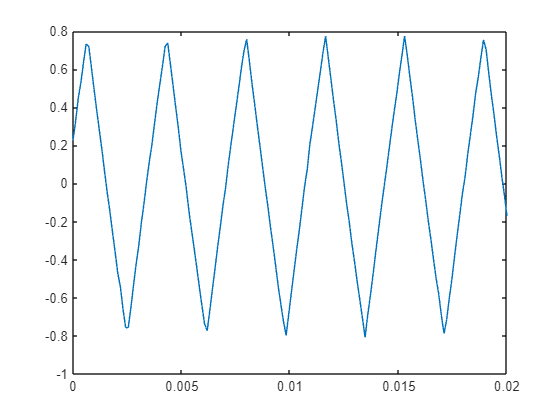

N_tri = length(triangle);
T = linspace(0,2,N_tri);
plot(T,triangle)
xlim([0,0.02])

#### Explore statistical model of the quantization error :

We want to see a uniform distribution of the quantization error along the representing bits.

- First, we want to normalize the signal since the quantizer assumes a dynamic range of [-1,1].

- Then we take the normalized signal and pass it through the quantizer.

- Finally we compare between the original signal and the quantized signal and plot the errors in a histogram.

We assume that the original 12bit accuracy holds all the information of the original signal.

We will examine the distribution of the error over the dynamic range for lower accuracies (8bit, 6bit ,etc.)

X = triangle/max(abs(triangle));

Q_error = @(X,S_bits) X - quantize(X,12,S_bits);

k = 8 ;
E = Q_error(X,k);

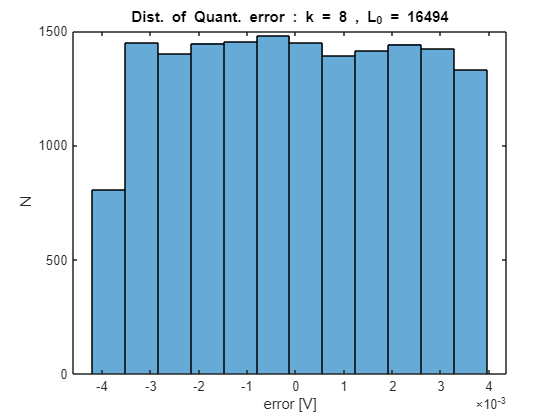

histogram(E,12)
title_str = "Dist. of Quant. error : k = " + num2str(k) + " , L_0 = " + num2str(length(triangle));

title(title_str)
xlabel("error [V]")
ylabel("N")